# EL2520 Computer Exercise 4

## 3.1 | Static Decoupling

### 3.1.1

s = tf('s');
sys = minphase;
% sys = nonminphase;
H = (s -1)/(s^2 +5)


H =
 
   s - 1
  -------
  s^2 + 5
 
Continuous-time transfer function.




A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;

I = eye(size(A));
G = C*inv(s*I-A)*B+D; % 2x2 trans. func.
% g11 = G(1,1);
% g12 = G(1,2); % Input 2 to output 1
% g21 = G(2,1); % Input 1 to output 2
% g22 = G(2,2);

G_inv = minreal(inv(G));
W_1 = evalfr(G_inv,0);
W_2 = eye(size(G));

G_tilde = W_2*G*W_1


G_tilde =
 
  From input 1 to output...
        -0.02872 s^2 + 0.002916 s + 0.0002237
   1:  ----------------------------------------
       s^3 + 0.1879 s^2 + 0.01137 s + 0.0002237
 
         0.04787 s^2 + 0.002246 s + 5.897e-11
   2:  ----------------------------------------
       s^3 + 0.1847 s^2 + 0.01073 s + 0.0002001
 
  From input 2 to output...
         0.04399 s^2 + 0.002246 s + 4.254e-16
   1:  ----------------------------------------
       s^3 + 0.1879 s^2 + 0.01137 s + 0.0002237
 
        -0.02639 s^2 + 0.003026 s + 0.0002001
   2:  ----------------------------------------
       s^3 + 0.1847 s^2 + 0.01073 s + 0.0002001
 
Continuous-time transfer function.



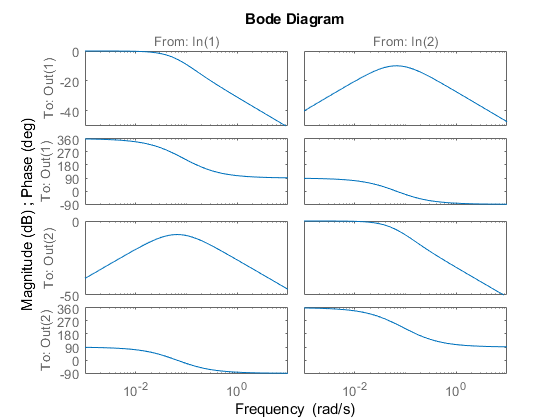

bode(G_tilde)

### 3.1.2